addpath('./tracking/')
addpath('./sample/')
addpath('./system/')

load US_sample_data
% This file contains two consecutive ultrasound(US) images with header
% information, namely rf1, and rf2. 

% rf1 and rf2 are struct variables. The field "rf" contains the radio 
% frequency (RF) data.
tpl = rf1.rf;
tar = rf2.rf;

% To demo our template tracking, we need to specify template and target, so
% we can compare the points in these 2 data frames. 

% Usually template is the previous frame (frame 1, rf1), and the target is
% the current frame (frame 2, rf2). In this setup, we will know the points'
% displacement, a 2D vector X(p) = ( u(p),v(p) ) for each point p. 

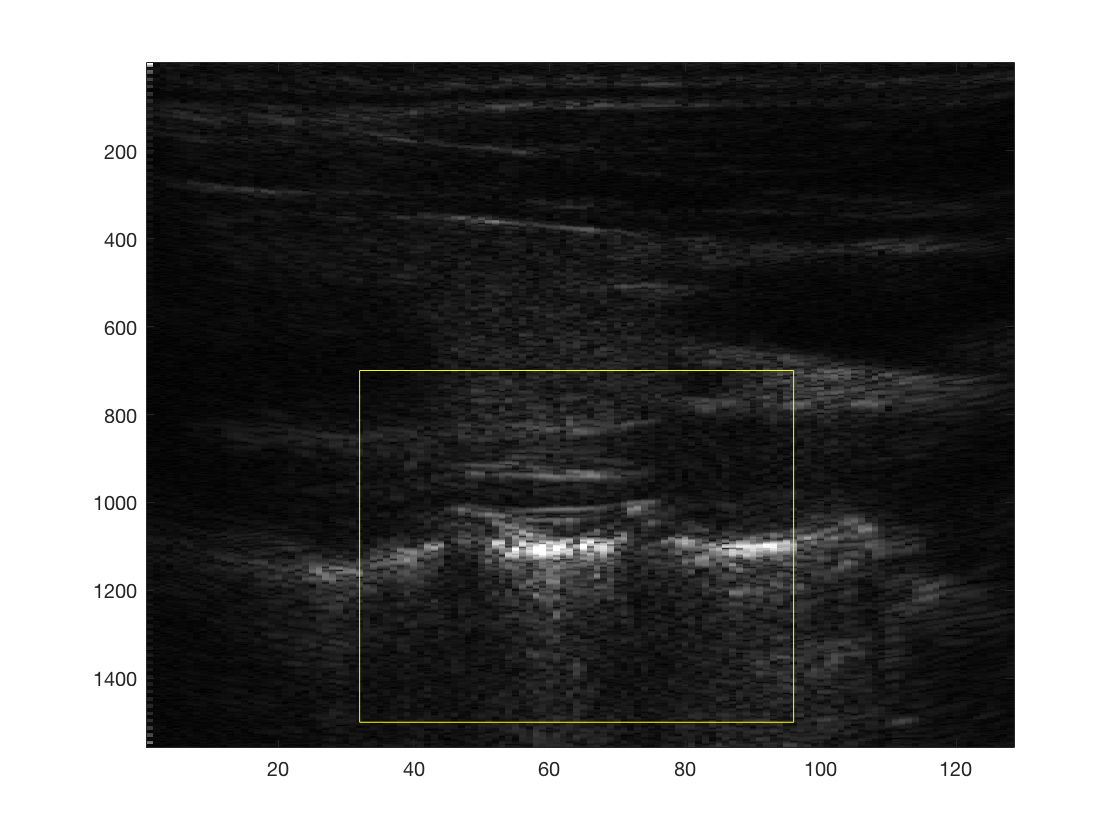

% Section 1: Visualize US RF data and the initial setting

% b_map is a B-mode mapping function that I developed to highlight
% bone-tissue interface. It is a linear mapping rather than log-compression
% mapping. For further information, please go into the code's description
image(b_map(tpl));

% For a lot of codes available online, they specify the region of interest
% (ROI) in such way: [x1, y1, w, h]. x, y are the dimensions in normal 2D 
% cartesian coordinates, or in other words, x is the left to right
% dimension and y is the top to bottom dimension. 
x1 = 32; y1 = 700; w = 64; h = 800;
initstate = [x1, y1, w, h];

% Visualize the rectangle ROI
rectangle('Position',initstate,'EdgeColor','y')

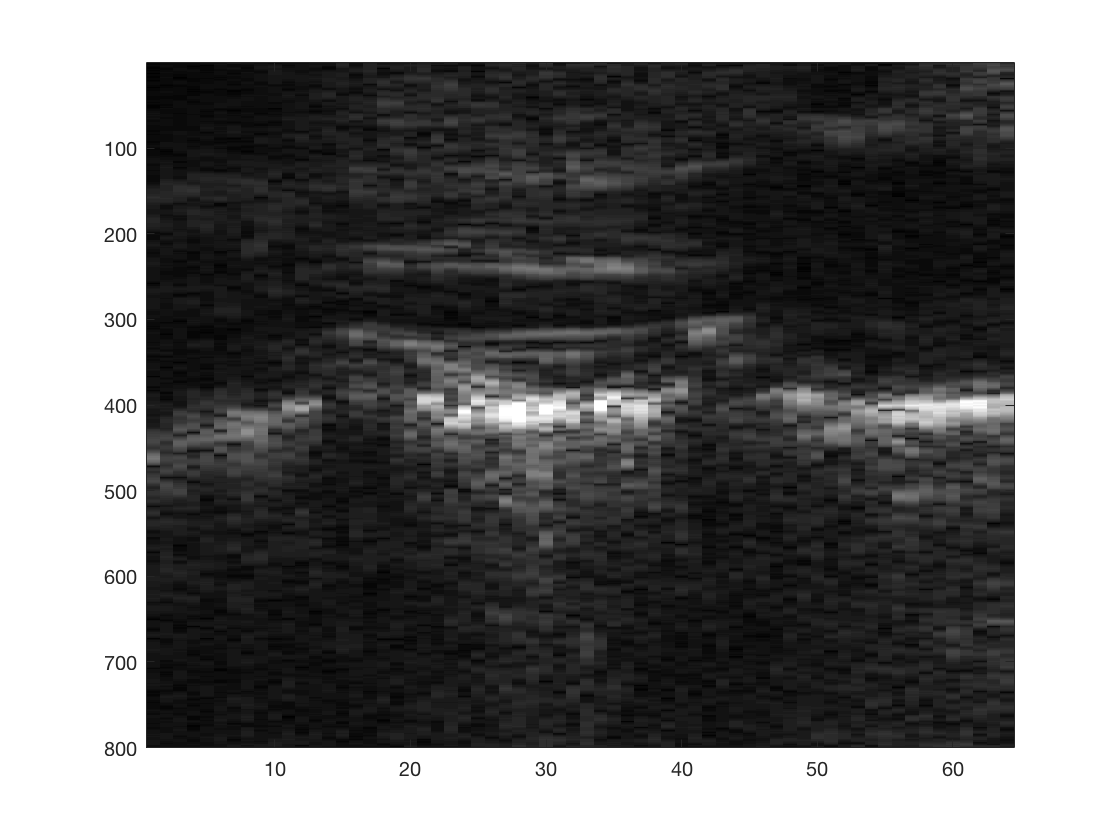


% MATLAB use row-first method to arrange 2D Matrix, or
% a 2D image. So we need to use a function to make things compatible.
st = state(initstate);

% st is a struct which has "x1", "y1", "x2", "y2", "w", "h" fields.
% Attention! Now "x", "y" no longer conforms to the x,y in Cartesian coordinate system
% Here, x is the 1st dimension of the 2D matrix, or the row index
% y is the 2nd dimension of the 2D matrix, or the column indx

% display the image of the ROI
im = tpl(st.x1:st.x1+st.h-1, st.y1:st.y1+st.w-1);
image(b_map(im));


% we are not using this variable "im". To avoid confusion, we will clear it
clearvars im;


%% Section 2: Defining method to perform template-matching tracking

% Recap some points we have made in the last section. The way we organize the image is different than our instinct, or the common way to specific image in computer vision
% Now in our program, the x, is the row index of 2D matrix, or the axial direction of ultrasound image, which usually has a fine resolution.
% We will name it the direction X.
% So the lateral direction, we will name it the Y direction. Y has maximum 128 line samples in a 128-element linear array.

% Search Range
% The template matching will need the search range in the X, Y. 
sX = 10;
sY = 20;

% Sometimes, we don't want to calculate every points in the ROI. We will downsample the image to reduce the computation complexity.
% Here we will perform a full computation and next demo a reduced version of tracking.
rX = h; % number of row sample in the X direction
cY = w; % number of column sample in the Y direction

% we now put things together in a struct, and check the integrity
method1 = [sX, sY, rX, cY];

kn1 = kernel(method1,st);

% Section 3: Applying the methods
% 

% Now everything is ready, and we will compute the displacement map
% In MATLAB live editor, the performance is much slower than using a normal script
result1 = NCorrEst(tpl,tar,st,kn1);

% u is in X direction, v is in Y direction, to put things back to normal Cartesian coordinates
% we need to switch the order when we visualize result
quiver(result1.v, result1.u);

% Now let's play with rX and cY
% 
% Goal: accelerate the speed of computation.
% We notice X direction has a lot of samples, maybe we don't need all of them. So we downsample the X direction to its 1/2;

rX = round(h/2); % integer needed

% Update method and kernel
method2 = [sX, sY, rX, cY];
kn2 = kernel(method2,st);

% Calculate
result2 = NCorrEst(tpl,tar,st,kn2);

% Display
quiver(result2.v, result2.u);
% if you check the size of result2's fields, it is half compared to result1's
% Also, the computation is much faster.

% Here is all about the usage of the NCorrEst
% Last but not the least, we hope to check its accuracy
% Let's run it with known displacement

% tpl remains the same
% We will apply a displacement (Axial:5 Lateral:2) to the tar and make up tar

tar = circshift(tpl,[5,2]);

result1 = NCorrEst(tpl,tar,st,kn1);
quiver(result1.v, result1.u);

% if you zoom in the quiver map, you will find all arrow are almost the same (5,2)




function st = state(initstate)
    % Unfortunately, MATLAB use column-first method to arrange 2D Matrix, or
    % a 2D image. So we need to use a function to make things compatible.
    
    % check if numbers need to be integer
    if any(initstate - round(initstate))
        disp('warning: initstate is not an integer vector');
    end

    
    initstate = round(initstate);
    y = initstate(1);% x axis at the Top left corner
    x = initstate(2);
    st.w = initstate(3);% width of the rectangle
    st.h = initstate(4);% height of the rectangle

    st.x1 = x;
    st.x2 = x+st.h-1;
    st.y1 = y;
    st.y2 = y+st.w-1;
end

function kn = kernel(set,state)
    % search radius in X/Y direction
    sx = set(1);
    sy = set(2);
    rx = set(3);
    cy = set(4);
    
    kn.sx = sx;
    kn.sy = sy;
    % # locs (rows,cols) that need to be tracked
    kn.rx = rx;
    kn.cy = cy;
    
    % region of interest width and height
    kn.w = state.w;
    kn.h = state.h;
    
    % default minimum elements in the lateral/axial direction
    hx = 7; 
    hy = 1;
    
    if kn.h/rx/2 > hx
        hx = floor(kn.h/rx/2);
    end
    
    if kn.w/cy/2 > hy
        hy = floor(kn.w/cy/2);
    end
        
    kn.hx = hx;
    kn.hy = hy;

end


